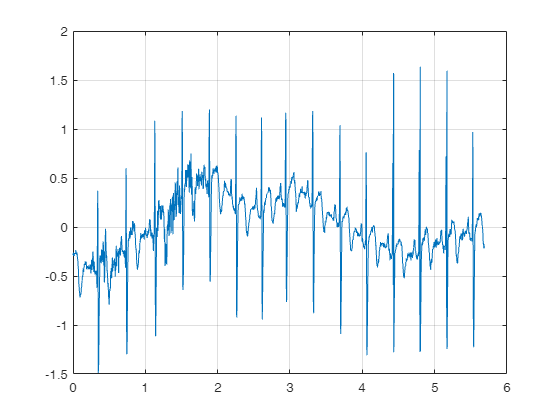

[data,annotations] = edfread("H:/181022/Аня_filtered.edf");
info = edfinfo("H:/181022/Аня_filtered.edf");
fs = info.NumSamples/seconds(info.DataRecordDuration);
ecg=data(:,3);
%plot(ecg);
fs2=fs(3);
load wecg
load mit200
ecg=detrend(wecg);
% ecg=detrend(ecgsig);
wt = tqwt(ecg,QualityFactor=3,Level=6);
mra = tqwtmra(wt,length(wecg),QualityFactor=3);
tm=linspace(0,length(wecg)/360,length(wecg));
figure();
plot(tm,ecg);
grid("on");

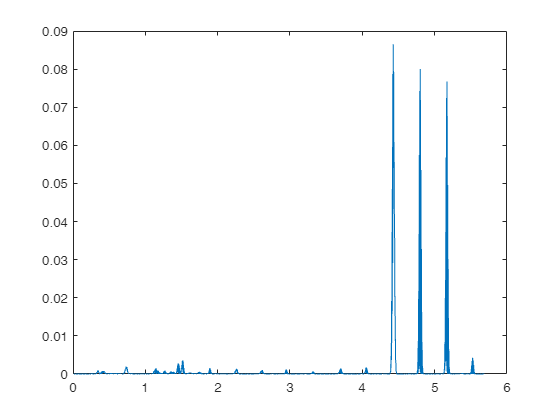

figure();
plot(tm,mra(3,:).^2);

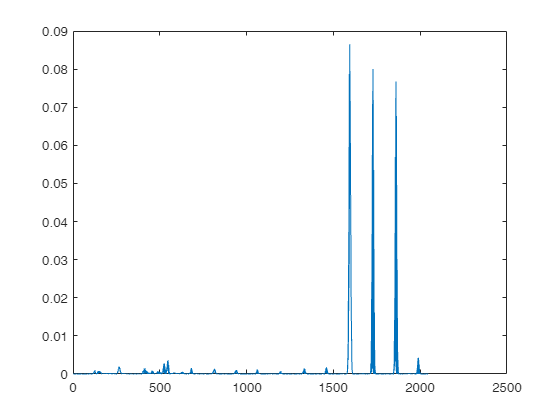


[qrspeaks,locs] = findpeaks(mra(3,:).^2,tm,...
    'MinPeakDistance',0.200);
figure();
plot(mra(3,:).^2);

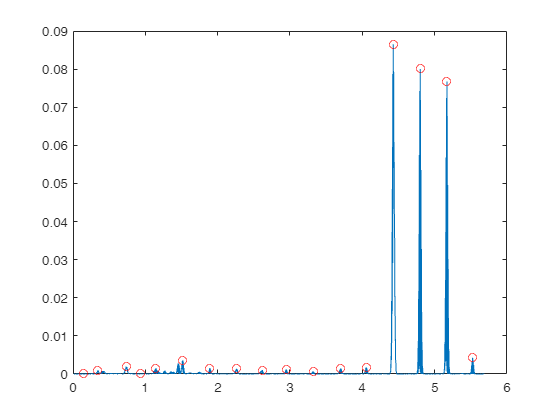

figure();
plot(tm,mra(3,:).^2);
hold on;
plot(locs,qrspeaks,'ro');

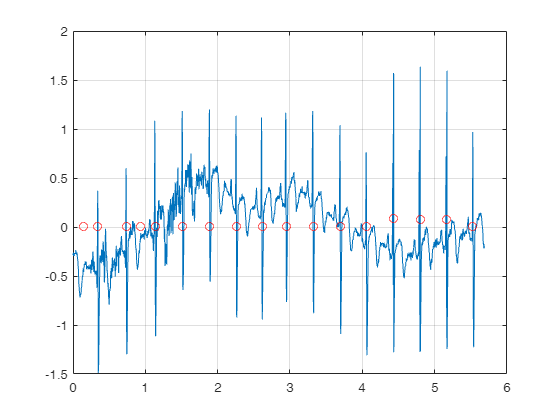

figure();
plot(tm,ecg);
hold on;
plot(locs,qrspeaks,'ro');
grid('on');